# The French–Harary–DeGroot model: theory and simulations of the report

% Bootstrap: walk up from this file until setup_paths.m is found, then put
% the library on the path. This works whether you are running the .m source
% or the generated .mlx, from any folder.
projectDir = fileparts(mfilename('fullpath'));
while ~isfile(fullfile(projectDir, 'setup_paths.m')) && ...
        ~strcmp(projectDir, fileparts(projectDir))
    projectDir = fileparts(projectDir);
end
addpath(projectDir);
setup_paths;

## Settings

saveEps = false leaves the figures on screen only; set it to true to write the .eps files of Part 2 into outDir. They are never written into FINAL/report/figures.

if ~exist('saveEps','var'), saveEps = false; end
if ~exist('outDir','var'),  outDir = fullfile(projectDir,'livescripts','report_figures'); end
if saveEps && ~isfolder(outDir), mkdir(outDir); end

## Part 1 – Theory (from ch01_fdg_v6.mlx, Sections 1.1–1.4)

## Direction convention

Every matrix in this project follows one rule:

Equivalently, row i lists whom agent i listens to, which is why the rows are the objects that must sum to one.

The two books in the repository draw the arrows in opposite directions: Proskurnikov & Tempo point them along the flow of influence, Bullo points them from the advice seeker to the advisor. THE MATRIX IS THE SAME; only the picture differs.

In this live script, Part 1 follows Proskurnikov & Tempo, so a stubborn agent is a source node; the report and Part 2 follow the course convention (an edge i → j means that agent i is influenced by agent j), so the same agent is a sink.

## 1.1 The French-DeGroot model of opinion formation

Describes a DT process of opinion formation in a group of $n$ agents, whose opinions are $x_1, \dots, x_n \text{ with } x_i\in\mathbb R$

System dynamics is described by the stochastic matrix $W = (w_{ij}) \in \mathbb R^{n \times n}$ where $w_{ij}>0, j=1, \dots, n$ defines the influence of agent $j$ on the opinion of agent $i$ at each time-step.

Hence the system equation is 

                                                             (M1.1)   $x(k+1) = Wx(k) = \sum_{j = 1}^nw_{ij}x_j(k) \forall i, \ k = 0, 1 , \dots$

The self-influence weight $w_{ii} \ge 0
$ indicates the agent's openness to the assimilation of other's opinions:

- $w_{ii} = 0
$ "open-minded" (completely relies on others' opinions)

- $w_{ii} = 1 \text{ and } w_{ij}=0 \forall j \neq i $ "stubborn" (anchored to its initial opinion $x_i (k) \equiv x_i(0) \text{ for } k = 0, 1 ,\dots
$

Agent's opinions can also be vectors $x^i = (x_{1i}, \dots,x_{mi})$, hence we get the opinion matrix $X = (x_{ij})\in \mathbb R ^ {n \times m}$ and we can rewrite the system dynamics as 

                                                                            (M1.2)    $X(k+1) = WX(k), \ k = 0,1, \dots$

Every column $x_i(k) = (x_{1i}(k),\dots x_{ni}(k))^T \in \mathbb R ^n \text{ of } X(k)$ evolves in accordance to M1.1. Hence M1.2 with a general stochastic matrix W is referred to as the French-DeGroot model.

## 1.2 Convergence and Consensus Criteria

The dynamics of M1.1 is "non-expansive" in the sense that 

                                                                            
$$\min_ix_i(0) \le \dots \le \min_ix_i(k) \le \min_ix_i(k+1) \\
\max_ix_i(0) \ge \dots \ge \max_ix_i(k) \ge \max_ix_i(k+1)$$


for any $k = 0, 1, \dots
$

Such system is Lyapunov stable but such stability is not asymptotic since $W$ always has eigenvalue at $1$.

Such model is **convergent **if for any initial condition $x(0)$ the limit exists $x(\infty) = \lim_{k \rightarrow \infty}x(k) = \lim_{k \rightarrow \infty}W^kx(0)$. A convergent model reaches consensus if $x_1(\infty) = \dots = x_n(\infty)

$ for any initial condition.

We call the matrix $W$** regular **if the limit $W^\infty = \lim_{k\rightarrow \infty} W^k$ exists and **fully regular **if, additionally, the rows of $W^\infty$ are identical (**i.e. **$W^\infty = \mathbb 1_np_\infty^T$ for some $p_\infty \in \mathbb R^n$).

**Lemma 1.1 **The model M1.1 is convergent (ie $W$ regular) $\iff$ $\lambda = 1$ is the only eigenvalue of $W$ on the unit circle $\left\{ \lambda \in \mathbb C :  | \lambda | = 1\right\}$. Such model reaches consensus (ie $W$ fully regular) $\iff$ this eigenvalue is simple, i.e the corresponding eigenspace is spanned by the vector $\mathbb 1$.

**Lemma 1.2 **For an irreducible stochastic matrix $W$ the model M1.1 is convergent $\iff$ $W$ is primitive, ie $W^k$ is a positive matrix for large k. In this case consensus is also reached.

**Lemma 1.3 **If the graph $\mathcal G = \mathcal G[W]$ is strong, then the model M1.1 reaches a consensus $\iff$ $\mathcal G$ is aperiodic. Otherwise, the model is not convergent and opinions oscillate for almost all $x(0)$.

**Theorem 1.1 **The model M1.1 is convergent $\iff$ all closed strong components in $\mathcal G [W]$ are aperiodic. The model M1.1 reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected and the only closed strong component is aperiodic

**Corollary 1.1 **Let the agents' self-weights be positive $w_{ii}>0$ for all $i$. Then, the model M1.1 is convergent. It reaches a consensus $\iff$ $\mathcal G[W]$ is quasi-strongly connected (ie has a directed spanning tree).

## 1.3 French-DeGroot: Dual Markov chain and social power

Matrix $W$ may be considered as a matrix of transition probabilities of some Markov chain with $n$ states. Denoting by $p_i(t)$ the probability of being at state $i$ at time $t$, the row vector $p^T(t) = (p_1(t),\dots,p_n(t))$ obeys the equation

                                                                        (M1.3)$p(k+1)^T = p(k)^TW, \ t = 0,1, \dots$

The convergence of M1.1, that is, regularity of $W$ implies that the probability distribution converges to the limit $p(\infty)^T = \lim_{k\rightarrow \infty} p(k)^T = p(0)^TW^\infty$. Consensus in M1.1 implies that $p(\infty) = p_\infty$ where $p_\infty$ is the vector from the regularity definition, ie, the Markov chain "forgets" its history and converges to the unique stationary distribution. Such chain is called regular or ergodic. 

The closed strong components in $\mathcal G[W]$ correspond to essential classes of states, whereas the remaining nodes correspond to inessential (or non-recurrent) states.

The standard ergodicity condition is that the essential class is unique and aperiodic, which is in fact equivalent to the second part of Theorem 1.1. First part of such thm states another known fact: *"Markov chain always converges to a stationary distribution *$\iff$ *all essential classes are aperiodic".*

Assuming that $W$ is fully regular, one notices that 

                                                                    (E1.1) $x(k) = W^kx(0) \rightarrow (p_\infty^Tx(0))\mathbb 1_n, \text{ for } k\rightarrow \infty$

The element $p_{\infty i}$ can thus be treated as a measure of **social power** of agent $i$, ie the weight of its initial opinion $x_i(0)$ in the final opinion of the group. 

The social power may be considered as a **centrality measure**, allowing to identify the most "important" (influential) nodes of a social network. It's similar to eigenvector centrality, which is defined as the left eigenvector of the conventional binary adjacency matrix. Usually centrality measures are introduced as functions of the graph topology while their relations to dynamical processes over graph are not well studied. French's model of social power introduces a dynamic mechanism of centrality measure and a decentralized algorithm M1.3 to compute it.

Consider the French model with $n=3$ agents, corresponding to the following graph                                      

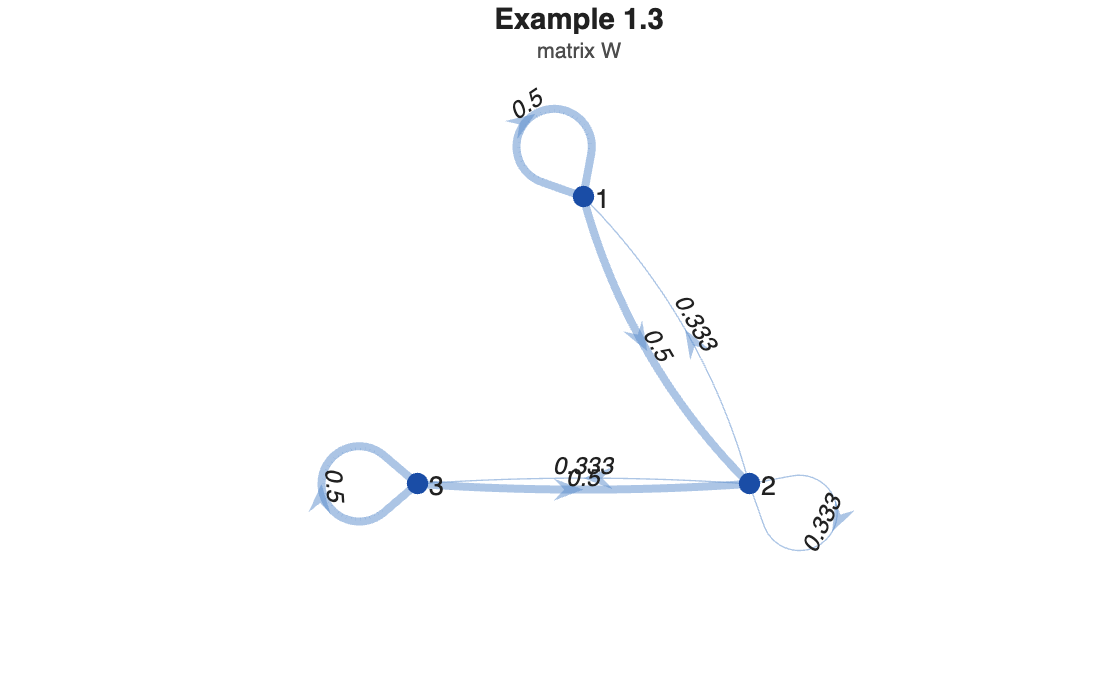

W = [1/2 1/2   0
     1/3 1/3 1/3
       0 1/2 1/2];
plot_graph(W, [], 'Title','Example 1.3', 'Subtitle','matrix W') 

One can expect that the "central" node 2 corresponds to the most influential agent in the group. This is confirmed by a straightforward computation: solving the system of equation $p_\infty^T = p_\infty^TW$ and $p_\infty^T \mathbb 1 = 1$, one obtains the vector of social powers $p_\infty^T = (2/7, 3/7, 2/7)$

x0 = [3;-1;5]

x0 =      3
    -1
     5


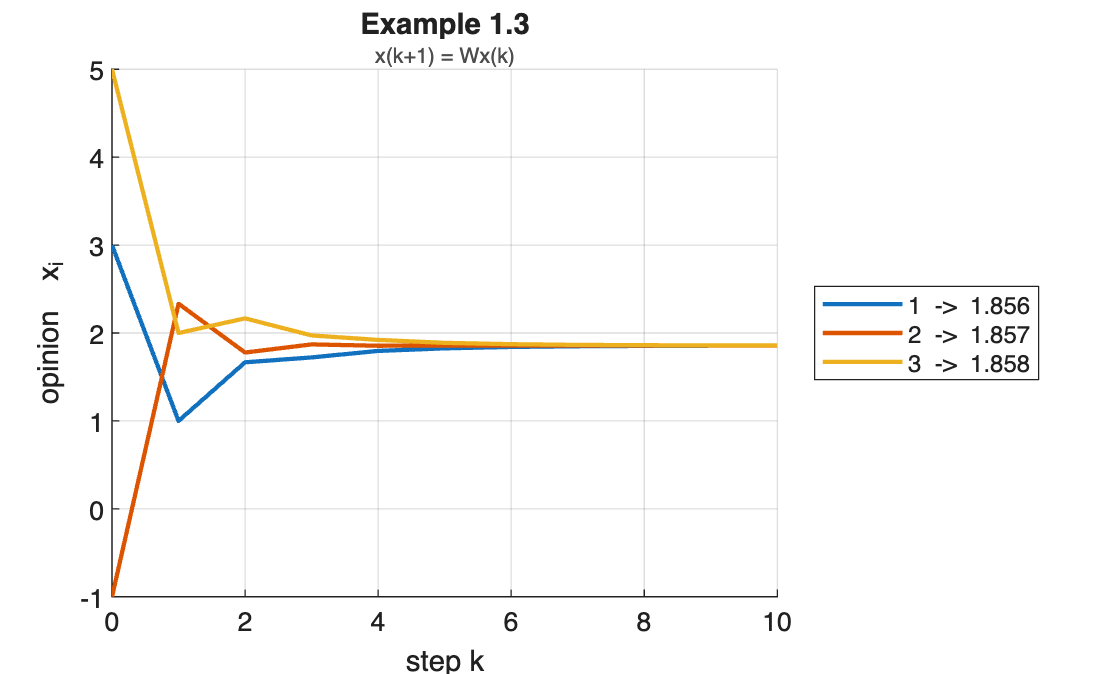

p  = social_power(W);          % p' = p'W,  p'1 = 1   ->  [2/7 3/7 2/7]
X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.3', 'Subtitle','x(k+1) = Wx(k)')

p' * x0                        % the consensus value

ans = 1.8571

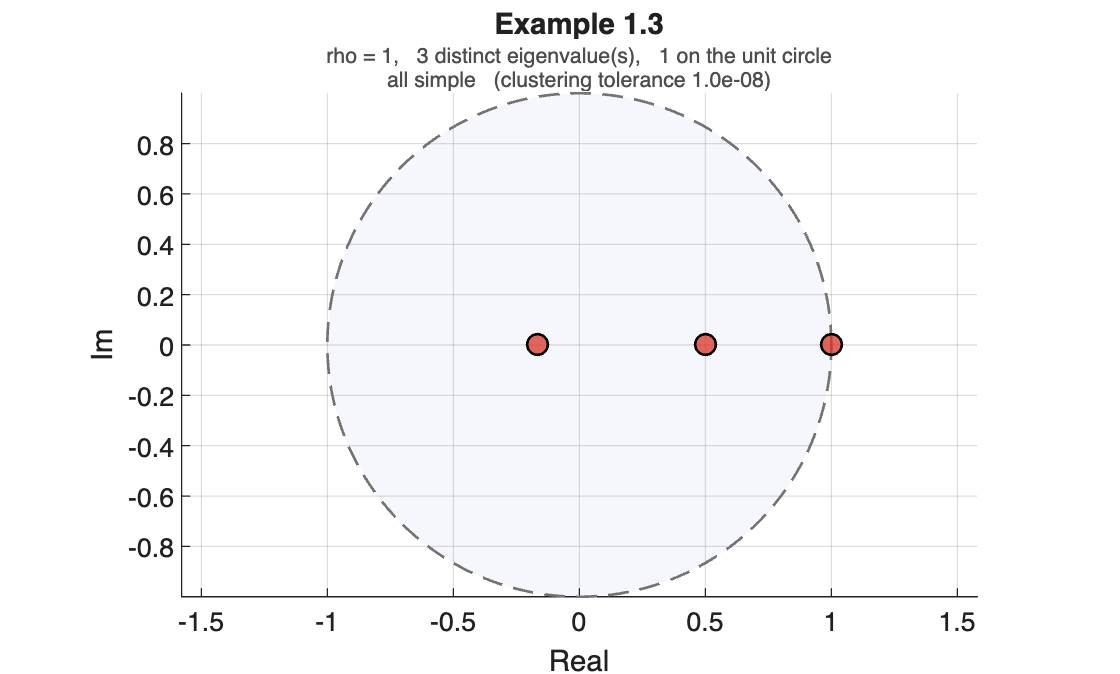

T = 3×5 table
     lambda        Re       Im    modulus    multiplicity
    ________    ________    __    _______    ____________

           1           1    0           1         1      
         0.5         0.5    0         0.5         1      
    -0.16667    -0.16667    0     0.16667         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','Example 1.3'); T

## 1.4 Stubborn agents in the French-DeGroot model

An agent is said to be **stubborn** if its opinion remains unchanged, independent of the other's opinions.

If the opinions obey the model  M1.1 then the agent $i$ is stubborn $x_i(k)\equiv x_i(0)$ $\iff$ $w_{ii}=1$. Such an agent corresponds to a source node in a graph $\mathcal G[W]$, ie a node having no incoming arcs but for the self-loop. **Theorem 1.1** implies that if $\mathcal G[W]$ has the only source, then the opinions reach a consensus (the source node is the only closed strong component of the graph).

If more than one stubborn agent exist (ie $\mathcal G[W]$ has several sources), then consensus among them is, obviously, impossible.  **Theorem 1.1** implies, however, that typically the opinions in such a group converge.

**Corollary 1.2 **Let the group have $s\ge1$ stubborn agents, influencing all other individuals (ie the set of source nodes is connected by walks to all other nodes of $\mathcal G[W]$). Then the model M1.1 is convergent.

Indeed, source nodes are the only closed strong components of $\mathcal G[W]$, which are obviously aperiodic.

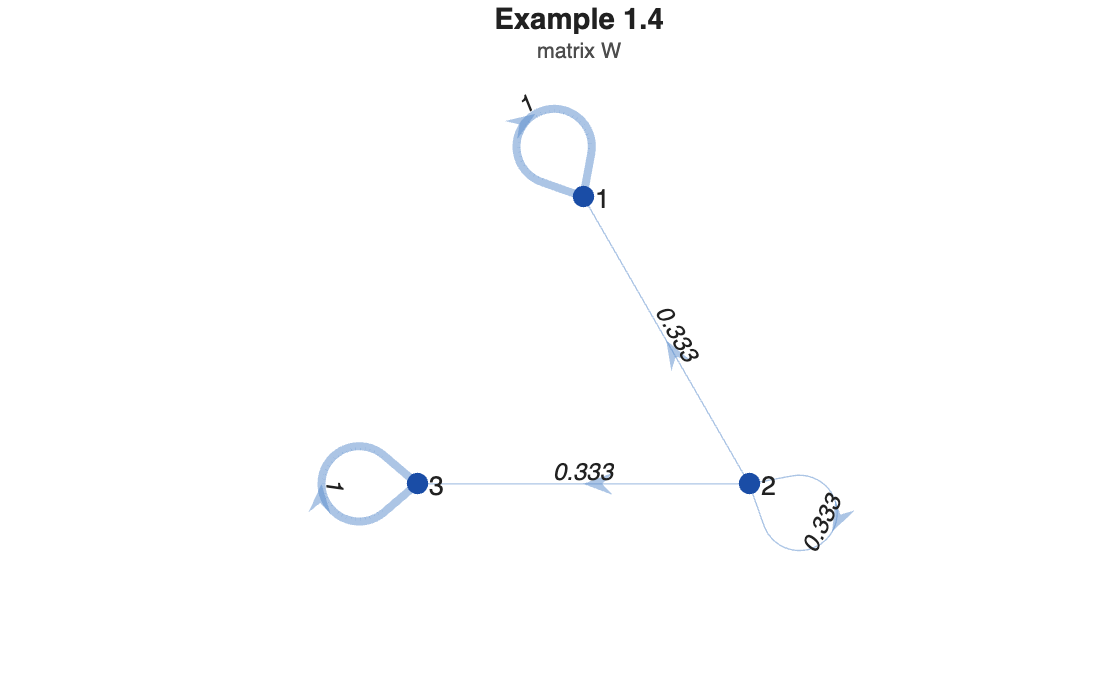

W = [1 0 0
     1/3 1/3 1/3
       0 0 1];
plot_graph(W, [], 'Title','Example 1.4', 'Subtitle','matrix W') 

x0 = [3;-1;5]

x0 =      3
    -1
     5


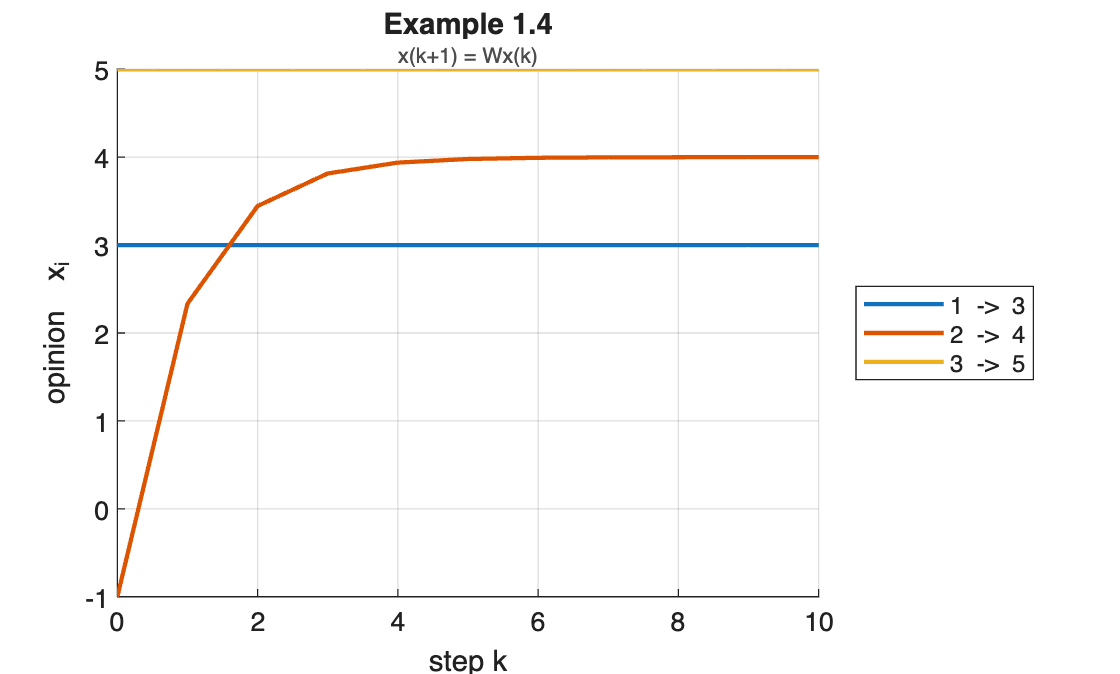

X  = sim_degroot(W, x0, 10);
plot_opinions(X, [], 'Title','Example 1.4', 'Subtitle','x(k+1) = Wx(k)')

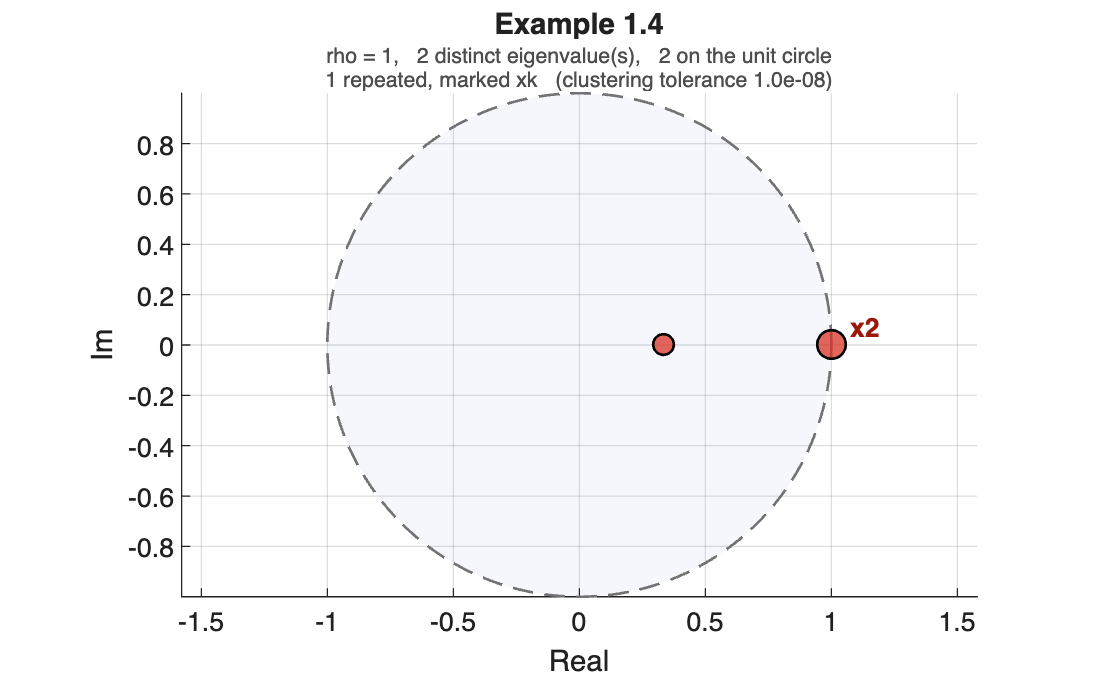

T = 2×5 table
    lambda       Re       Im    modulus    multiplicity
    _______    _______    __    _______    ____________

          1          1    0           1         2      
    0.33333    0.33333    0     0.33333         1      


figure; T = plot_eigenvalues(W, 'discrete', 'Title','Example 1.4'); T

## Part 2 – Simulations of the report (Section 2.2)

% Common parameters of Section 2.2 of the report: the two networks of Figure 1 on
% n = 6 agents (no self-loops), the initial opinions, and one colour per agent kept
% the same in every figure. Cleared first, so nothing from Part 1 leaks in.
clearvars -except saveEps outDir projectDir

n   = 6;
agentColour = lines(n);            % same colour per agent in every figure
Acyc  = rep_cycle_matrix(n);       % directed cycle:     a_{i,i+1} = 1
Aring = rep_ring_matrix(n);        % bidirectional ring: a_{i,i-1} = a_{i,i+1} = 1/2
x0 = [0; 0.2; 0.4; 0.6; 0.8; 1];   % initial opinions, the same in every figure

tol  = 1e-3;                       % tolerance of the numerical checks
pass = true;                       % set to false by the first check that fails

## Figure 2 – Self-weights, stubbornness and convergence

Report: Section 2.2.2, Figure 2 (FINAL/report/figures/fdg_convergence.eps).

Caption in the report:

Opinions $x_i(k)$ in the two networks of Figure 1 (top: directed cycle; bottom: bidirectional ring) for three values of the self-weight $t$ of agent $1$ (columns), with $x(0) = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $. Agent $1$ is marked with dots.

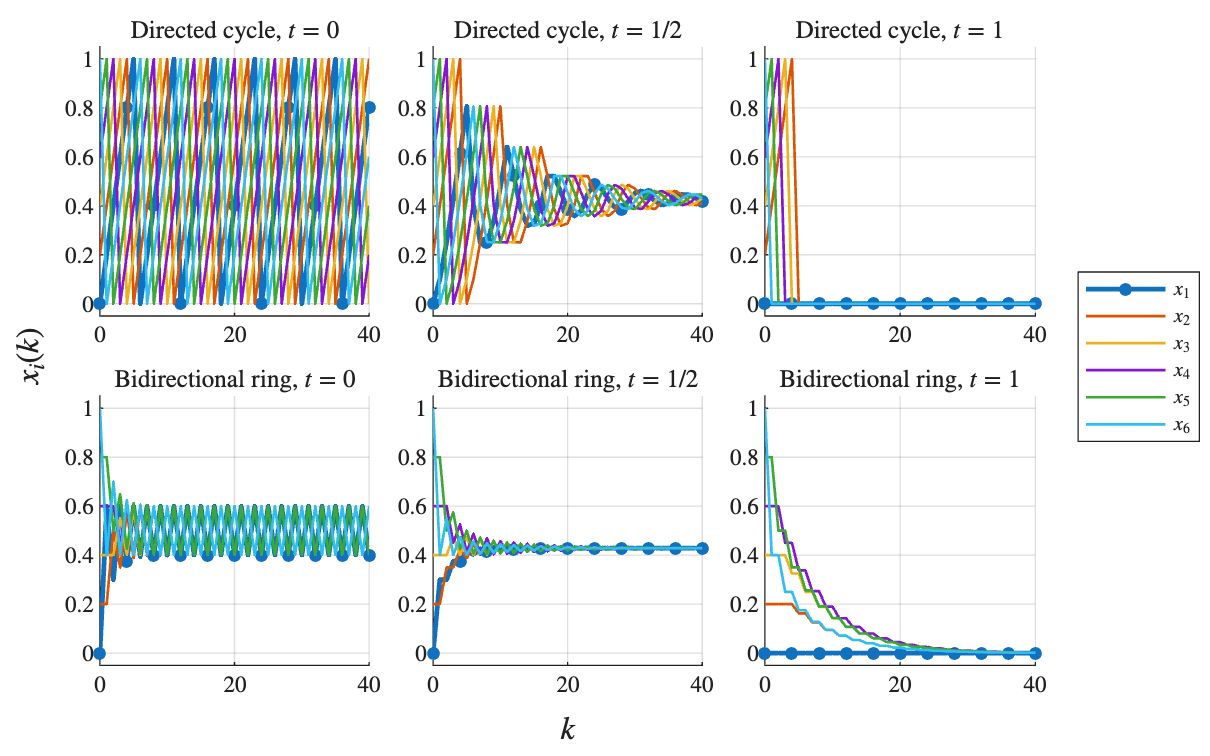

% Report Figure 2. The FDG model (1), x(k+1) = A(t) x(k), on the two networks of
% report Figure 1. A(t) is the self-weight modification (3): only row 1 of A becomes
% (1-t) a_1' + t e_1', so t = 0 leaves the network untouched and t = 1 makes agent 1
% stubborn. Panels: one row per network (top directed cycle, bottom bidirectional
% ring), one column per value of t (0, 1/2, 1); agent 1 is the thick curve with dots.
K  = 40;
ts = [0, 0.5, 1];
nets = {'Directed cycle', Acyc; 'Bidirectional ring', Aring};

fig1 = rep_new_figure(16, 10);
tl = tiledlayout(fig1, 2, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
h = gobjects(n, 1);
for r = 1:2
    for c = 1:3
        ax = nexttile(tl);
        hold(ax, 'on');
        X = rep_simulate(rep_self_weight(nets{r,2}, ts(c)), x0, K);
        for i = 1:n
            if i == 1                       % agent 1 is highlighted
                h(i) = plot(ax, 0:K, X(i,:), '-o', 'Color', agentColour(i,:), ...
                    'LineWidth', 1.8, 'MarkerSize', 3, ...
                    'MarkerFaceColor', agentColour(i,:), 'MarkerIndices', 1:4:K+1);
            else
                h(i) = plot(ax, 0:K, X(i,:), '-', 'Color', agentColour(i,:), ...
                    'LineWidth', 1.0);
            end
        end
        grid(ax, 'on');
        ax.GridAlpha = 0.15;
        ylim(ax, [-0.05, 1.05]);
        xlim(ax, [0, K]);
        title(ax, sprintf('%s, $t = %s$', nets{r,1}, rep_tex_frac(ts(c))), ...
            'Interpreter', 'latex', 'FontWeight', 'normal');
        hold(ax, 'off');
    end
end
xlabel(tl, '$k$', 'Interpreter', 'latex');
ylabel(tl, '$x_i(k)$', 'Interpreter', 'latex');
lgd = legend(h, arrayfun(@(i) sprintf('$x_%d$', i), 1:n, 'UniformOutput', false), ...
    'Interpreter', 'latex');
lgd.Layout.Tile = 'east';

if saveEps
    rep_save_eps(fig1, fullfile(outDir, 'fdg_convergence.eps'));
end
% Checks 1 and 3 of make_fdg_figures.m, the ones that concern the trajectories above:
% the spectrum of A(t) behind each column, and how many steps the directed cycle needs
% at t = 1 before every opinion is agent 1's.
% --- check 1: eigenvalues --------------------------------------------
fprintf('\n--- 1. eigenvalues of A(t), sorted ---\n');


--- 1. eigenvalues of A(t), sorted ---


expected = { ...
    'directed', 0.0, exp(2i*pi*(0:5)/6).'; ...
    'directed', 0.5, [1; -0.823; -0.373+0.759i; -0.373-0.759i; 0.535+0.751i; 0.535-0.751i]; ...
    'directed', 1.0, [1; 0; 0; 0; 0; 0]; ...
    'ring',     0.0, [1; 0.5; 0.5; -0.5; -0.5; -1]; ...
    'ring',     0.5, [1; 0.623; 0.5; -0.223; -0.5; -0.901]; ...
    'ring',     1.0, [1; 0.866; 0.5; 0; -0.5; -0.866]};
for r = 1:size(expected,1)
    if strcmp(expected{r,1}, 'directed'), A0 = Acyc; else, A0 = Aring; end
    ev  = rep_sort_eig(eig(rep_self_weight(A0, expected{r,2})));
    exv = rep_sort_eig(expected{r,3});
    d   = max(abs(ev - exv));
    pass = pass && (d <= tol);
    fprintf('  %-9s t = %.1f : %s\n', expected{r,1}, expected{r,2}, rep_fmt_eig(ev));
    if d > tol
        fprintf('      MISMATCH, expected %s   (max diff %.2e)\n', rep_fmt_eig(exv), d);
    end
end

  directed  t = 0.0 : 1.0000  0.5000+0.8660i  0.5000-0.8660i  -0.5000+0.8660i  -0.5000-0.8660i  -1.0000
  directed  t = 0.5 : 1.0000  0.5348+0.7507i  0.5348-0.7507i  -0.3733+0.7587i  -0.3733-0.7587i  -0.8231
  directed  t = 1.0 : 1.0000  0.0000  0.0000  0.0000  0.0000  0.0000
  ring      t = 0.0 : 1.0000  0.5000  0.5000  -0.5000  -0.5000  -1.0000
  ring      t = 0.5 : 1.0000  0.6235  0.5000  -0.2225  -0.5000  -0.9010
  ring      t = 1.0 : 1.0000  0.8660  0.5000  -0.0000  -0.5000  -0.8660


% --- check 3: consensus time, directed cycle at t = 1 -----------------
fprintf('\n--- 3. directed cycle, t = 1: first k with spread < 1e-12 ---\n');


--- 3. directed cycle, t = 1: first k with spread < 1e-12 ---


Xs = rep_simulate(rep_self_weight(Acyc, 1), x0, K);
kk = find(max(Xs,[],1) - min(Xs,[],1) < 1e-12, 1) - 1;   % column 1 is k = 0
if isempty(kk)
    fprintf('  never reached within k = %d   MISMATCH, expected k = 5\n', K);
    pass = false;
else
    fprintf('  k = %d\n', kk);
    if kk ~= 5
        fprintf('      MISMATCH, expected k = 5\n');
        pass = false;
    end
end

  k = 5


## Figure 3 – Self-weights, stubbornness and social power

Report: Section 2.2.3, Figure 3 (FINAL/report/figures/fdg_social_power.eps).

Caption in the report:

Top: social power of agent $1$ ($w_1$) and of agent $2$ ($w_2$) as a function of the self-weight $t \in (0,1]$ of agent $1$. Bottom: consensus value $w^\top x(0)$ for $x(0) = (0,\, 0.2,\, 0.4,\, 0.6,\, 0.8,\, 1)^\top $; the dashed lines mark the average of $x(0)$ and $x_1(0)$. Both panels are computed numerically in the directed cycle (dots) and in the bidirectional ring (crosses); the two networks give the same values.

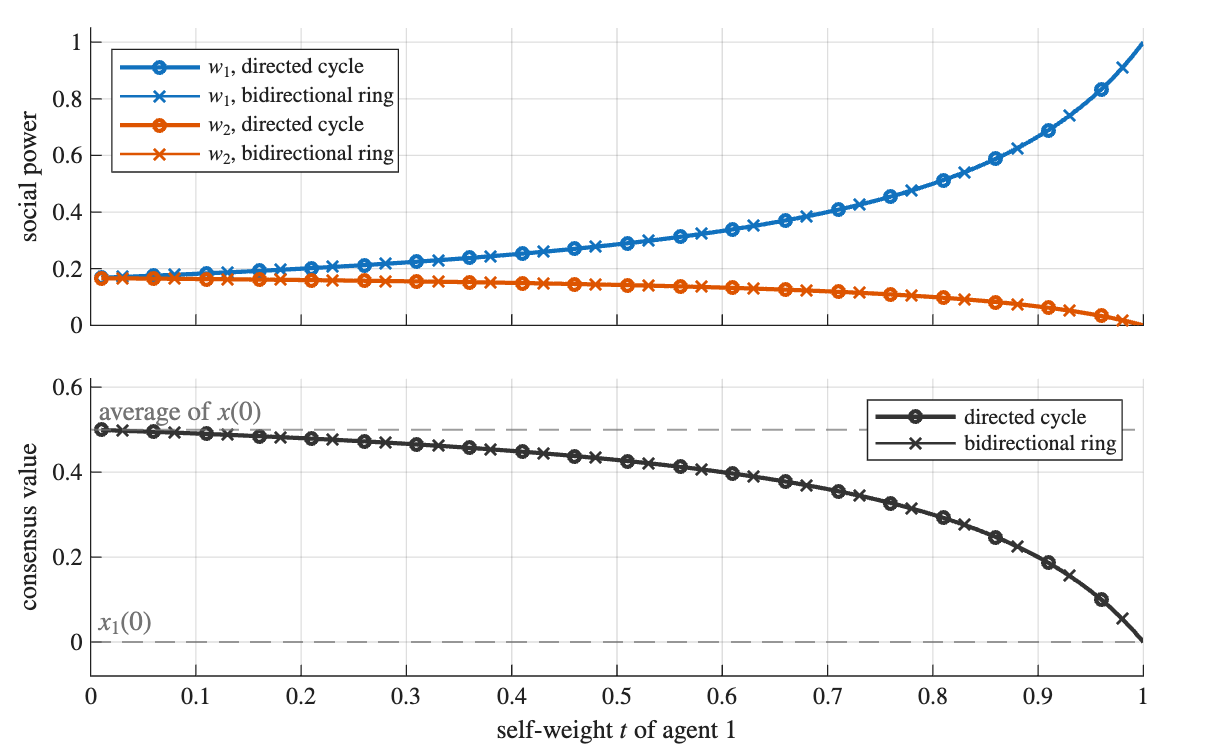

% Report Figure 3. The social power w(t) of (2), that is the left eigenvector of A(t)
% for the eigenvalue 1 normalised to sum 1, on a grid of t; t = 0 is left out because
% the plain networks reach no consensus. Top panel: w_1(t) and w_2(t), dots on the
% directed cycle and crosses on the bidirectional ring. Bottom panel: the consensus
% value w(t)' x(0) the group settles on, with the average of x(0) and x_1(0) marked by
% the two dashed lines.
tg = 0.01:0.01:1;                   % t = 0 excluded: no consensus there
Wc = zeros(n, numel(tg));
Wr = zeros(n, numel(tg));
for j = 1:numel(tg)
    Wc(:,j) = rep_social_power(rep_self_weight(Acyc,  tg(j)));
    Wr(:,j) = rep_social_power(rep_self_weight(Aring, tg(j)));
end
alphaC = x0.' * Wc;                 % consensus value alpha(t) = w(t)' x(0)
alphaR = x0.' * Wr;

fig2 = rep_new_figure(16, 10);
tl2 = tiledlayout(fig2, 2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
c1  = agentColour(1,:);  c2 = agentColour(2,:);
cA  = [0.20 0.20 0.20];             % one quantity, two networks: markers separate them
mkC = 1:5:numel(tg);                % markers every 5th point, offset between the two
mkR = 3:5:numel(tg);                % networks so both stay visible where they overlap

% --- top panel: social power ---------------------------------------
ax1 = nexttile(tl2);
hold(ax1, 'on');
plot(ax1, tg, Wc(1,:), '-o', 'Color', c1, 'LineWidth', 1.6, 'MarkerSize', 4, ...
    'MarkerIndices', mkC, 'DisplayName', '$w_1$, directed cycle');
plot(ax1, tg, Wr(1,:), '-x', 'Color', c1, 'LineWidth', 1.0, 'MarkerSize', 6, ...
    'MarkerIndices', mkR, 'DisplayName', '$w_1$, bidirectional ring');
plot(ax1, tg, Wc(2,:), '-o', 'Color', c2, 'LineWidth', 1.6, 'MarkerSize', 4, ...
    'MarkerIndices', mkC, 'DisplayName', '$w_2$, directed cycle');
plot(ax1, tg, Wr(2,:), '-x', 'Color', c2, 'LineWidth', 1.0, 'MarkerSize', 6, ...
    'MarkerIndices', mkR, 'DisplayName', '$w_2$, bidirectional ring');
grid(ax1, 'on');
ax1.GridAlpha = 0.15;
xlim(ax1, [0, 1]);
ylim(ax1, [0, 1.05]);
ax1.XTickLabel = {};                % horizontal axis shared with the panel below
ylabel(ax1, 'social power', 'Interpreter', 'latex');
legend(ax1, 'Interpreter', 'latex', 'Location', 'northwest');
hold(ax1, 'off');

% --- bottom panel: consensus value ----------------------------------
ax2 = nexttile(tl2);
hold(ax2, 'on');
ref = yline(ax2, mean(x0), '--', 'average of $x(0)$', ...
    'Color', [0.45 0.45 0.45], 'LineWidth', 0.75, 'Interpreter', 'latex', ...
    'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top');
ref.Annotation.LegendInformation.IconDisplayStyle = 'off';
ref = yline(ax2, x0(1), '--', '$x_1(0)$', ...
    'Color', [0.45 0.45 0.45], 'LineWidth', 0.75, 'Interpreter', 'latex', ...
    'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'top');
ref.Annotation.LegendInformation.IconDisplayStyle = 'off';
plot(ax2, tg, alphaC, '-o', 'Color', cA, 'LineWidth', 1.6, 'MarkerSize', 4, ...
    'MarkerIndices', mkC, 'DisplayName', 'directed cycle');
plot(ax2, tg, alphaR, '-x', 'Color', cA, 'LineWidth', 1.0, 'MarkerSize', 6, ...
    'MarkerIndices', mkR, 'DisplayName', 'bidirectional ring');
grid(ax2, 'on');
ax2.GridAlpha = 0.15;
xlim(ax2, [0, 1]);
ylim(ax2, [-0.08, 0.62]);
xlabel(ax2, 'self-weight $t$ of agent 1', 'Interpreter', 'latex');
ylabel(ax2, 'consensus value', 'Interpreter', 'latex');
legend(ax2, 'Interpreter', 'latex', 'Location', 'northeast');
hold(ax2, 'off');


if saveEps
    rep_save_eps(fig2, fullfile(outDir, 'fdg_social_power.eps'));
end
% Checks 2, 4, 5, 6 and 7 of make_fdg_figures.m: the two values of w(t) read off the
% top panel, the consensus values of the bottom panel, the fact that the dynamics
% really reach them, and the fact that the two networks give the same curves.
% --- check 2: social power at t = 0.5 and t = 1 -----------------------
fprintf('\n--- 2. social power w(t) ---\n');


--- 2. social power w(t) ---


for tv = [0.5, 1.0]
    for r = 1:2
        if r == 1, nm = 'directed'; A0 = Acyc; else, nm = 'ring'; A0 = Aring; end
        w = rep_social_power(rep_self_weight(A0, tv));
        if tv == 0.5
            exw = [2/7; repmat(1/7, n-1, 1)];
        else
            exw = [1; zeros(n-1,1)];
        end
        d = max(abs(w - exw));
        pass = pass && (d <= tol);
        fprintf('  %-9s t = %.1f : w = [%s]\n', nm, tv, ...
            strjoin(compose('%.4f', w.'), ' '));
        if d > tol
            fprintf('      MISMATCH, expected [%s]   (max diff %.2e)\n', ...
                strjoin(compose('%.4f', exw.'), ' '), d);
        end
    end
end

  directed  t = 0.5 : w = [0.2857 0.1429 0.1429 0.1429 0.1429 0.1429]
  ring      t = 0.5 : w = [0.2857 0.1429 0.1429 0.1429 0.1429 0.1429]
  directed  t = 1.0 : w = [1.0000 0.0000 0.0000 0.0000 0.0000 0.0000]
  ring      t = 1.0 : w = [1.0000 0.0000 0.0000 0.0000 0.0000 0.0000]


% --- check 4: the two networks give the same social power -------------
fprintf('\n--- 4. max |w_cycle(t) - w_ring(t)| over the grid ---\n');


--- 4. max |w_cycle(t) - w_ring(t)| over the grid ---


dmax = max(abs(Wc - Wr), [], 'all');
fprintf('  %.3e\n', dmax);

  9.992e-16


if dmax > 1e-10
    fprintf('      MISMATCH, expected numerically zero\n');
    pass = false;
end

% --- check 5: consensus value at selected t ---------------------------
fprintf('\n--- 5. consensus value alpha(t) = w(t)^T x(0) ---\n');


--- 5. consensus value alpha(t) = w(t)^T x(0) ---


for tv = [0.01, 0.5, 1.0]
    ac = x0.' * rep_social_power(rep_self_weight(Acyc,  tv));
    ar = x0.' * rep_social_power(rep_self_weight(Aring, tv));
    if tv == 0.01
        exa = 0.5;    tolA = 5e-3;   % w is near uniform here, not exactly uniform
    elseif tv == 0.5
        exa = 3/7;    tolA = tol;
    else
        exa = x0(1);  tolA = tol;
    end
    fprintf('  t = %.2f : directed %.4f   ring %.4f   (expected about %.4f)\n', ...
        tv, ac, ar, exa);
    if max(abs([ac, ar] - exa)) > tolA
        fprintf('      MISMATCH, expected about %.4f within %.1e\n', exa, tolA);
        pass = false;
    end
end

  t = 0.01 : directed 0.4992   ring 0.4992   (expected about 0.5000)
  t = 0.50 : directed 0.4286   ring 0.4286   (expected about 0.4286)
  t = 1.00 : directed 0.0000   ring 0.0000   (expected about 0.0000)



% --- check 6: the dynamics really reach alpha(t) ----------------------
fprintf('\n--- 6. dynamics vs alpha(t): max |x(2000) - alpha(t) 1_6| ---\n');


--- 6. dynamics vs alpha(t): max |x(2000) - alpha(t) 1_6| ---


for tv = [0.25, 0.5, 0.75]
    for r = 1:2
        if r == 1, nm = 'directed'; A0 = Acyc; else, nm = 'ring'; A0 = Aring; end
        At = rep_self_weight(A0, tv);
        a  = x0.' * rep_social_power(At);
        Xl = rep_simulate(At, x0, 2000);
        d  = max(abs(Xl(:,end) - a));
        fprintf('  %-9s t = %.2f : %.3e\n', nm, tv, d);
        if d > 1e-10
            fprintf('      MISMATCH, expected below 1e-10\n');
            pass = false;
        end
    end
end

  directed  t = 0.25 : 1.665e-16
  ring      t = 0.25 : 6.661e-16
  directed  t = 0.50 : 1.110e-16
  ring      t = 0.50 : 2.776e-16
  directed  t = 0.75 : 2.776e-16
  ring      t = 0.75 : 3.331e-16



% --- check 7: the two networks give the same consensus value ----------
fprintf('\n--- 7. max |alpha_cycle(t) - alpha_ring(t)| over the grid ---\n');


--- 7. max |alpha_cycle(t) - alpha_ring(t)| over the grid ---


damax = max(abs(alphaC - alphaR));
fprintf('  %.3e\n', damax);

  6.106e-16


if damax > 1e-10
    fprintf('      MISMATCH, expected numerically zero\n');
    pass = false;
end

## Summary of the checks

fprintf('\n%s\n', repmat('=', 1, 50));

if pass
    fprintf('ALL CHECKS PASSED\n\n');
else
    fprintf('SOME CHECKS FAILED - see the MISMATCH lines above\n\n');
end

ALL CHECKS PASSED



## Local functions

The helpers of make_fdg_figures.m, renamed with the prefix rep_ so that they cannot shadow social_power of lib/ or the built-in export.

function A = rep_cycle_matrix(n)
%CYCLE_MATRIX  Directed cycle: agent i is influenced only by agent i+1.
    A = zeros(n);
    for i = 1:n
        A(i, mod(i, n) + 1) = 1;
    end
end

% ---------------------------------------------------------------------
function A = rep_ring_matrix(n)
%RING_MATRIX  Bidirectional ring: agent i is influenced by i-1 and i+1.
    A = zeros(n);
    for i = 1:n
        A(i, mod(i - 2, n) + 1) = 0.5;
        A(i, mod(i,     n) + 1) = 0.5;
    end
end

% ---------------------------------------------------------------------
function A = rep_self_weight(A, t)
%SELF_WEIGHT  Give agent 1 a self-weight t, leaving every other row alone.
    A(1,:) = (1 - t) * A(1,:);
    A(1,1) = A(1,1) + t;
end

% ---------------------------------------------------------------------
function X = rep_simulate(A, x0, K)
%SIMULATE  x(k+1) = A x(k); column k+1 of X is x(k).
    X = zeros(numel(x0), K + 1);
    X(:,1) = x0;
    for k = 1:K
        X(:,k+1) = A * X(:,k);
    end
end

% ---------------------------------------------------------------------
function w = rep_social_power(A)
%SOCIAL_POWER  Left eigenvector of A for the eigenvalue 1, normalised to sum 1.
    [V, D] = eig(A.');
    [~, j] = min(abs(diag(D) - 1));
    w = real(V(:,j));
    w = w / sum(w);
end

% ---------------------------------------------------------------------
function e = rep_sort_eig(e)
%SORT_EIG  Deterministic ordering: real part descending, then imaginary part.
    e = e(:);
    [~, idx] = sortrows([-round(real(e), 6), -round(imag(e), 6)]);
    e = e(idx);
end

% ---------------------------------------------------------------------
function s = rep_fmt_eig(e)
%FMT_EIG  Eigenvalue list to 4 decimals, real ones printed without "+0i".
    parts = cell(1, numel(e));
    for k = 1:numel(e)
        if abs(imag(e(k))) < 1e-10
            parts{k} = sprintf('%.4f', real(e(k)));
        else
            parts{k} = sprintf('%.4f%+.4fi', real(e(k)), imag(e(k)));
        end
    end
    s = strjoin(parts, '  ');
end

% ---------------------------------------------------------------------
function s = rep_tex_frac(t)
%TEX_FRAC  Nice LaTeX for the three values of t used in the titles.
    if abs(t - 0.5) < eps
        s = '1/2';
    else
        s = sprintf('%g', t);
    end
end

% ---------------------------------------------------------------------
function fig = rep_new_figure(wcm, hcm)
%REP_NEW_FIGURE  Figure of the given size in centimetres, 9 pt text.
%   Same as NEW_FIGURE of make_fdg_figures.m, but visible, so that the
%   figures appear in the live script.
    fig = figure('Units', 'centimeters', ...
        'Position', [2, 2, wcm, hcm], 'Color', 'w');
    set(fig, 'DefaultAxesFontSize', 9, 'DefaultTextFontSize', 9, ...
             'DefaultLegendFontSize', 9, 'DefaultAxesTickLabelInterpreter', 'latex');
    fig.PaperUnits = 'centimeters';
    fig.PaperPosition = [0, 0, wcm, hcm];
    fig.PaperSize = [wcm, hcm];
end

% ---------------------------------------------------------------------
function rep_save_eps(fig, file)
%SAVE_EPS  Vector colour EPS, with a fallback for older MATLAB releases.
    if exist('exportgraphics', 'file') == 2
        exportgraphics(fig, file, 'ContentType', 'vector');
    else
        print(fig, file, '-depsc', '-vector');
    end
end